clc; close all;

% Motor Constants
noLoadCurrent = 2.1; % Amp
noLoadSpeed = 5600; % RPM
noLoadSpeed_rad = noLoadSpeed * 2*pi / 60; % rad/s
Km = 0.04025; % Nm / Amp


R = 0.3; % 0.19; % Ohms
L = 188e-6; %Henrys

s = tf('s');

% Position to Angle Transforms

% Z = zeros(2);
theta_to_xy = [1,1;1,-1]*3.5/2;
% D_inv = inv(D);


J_X = 550 / 1000 / 100^2; %kg*m^2
J_Y = 1750 / 1000 / 100^2; %kg*m^2
J_theta = 612 / 1000 / 100^2; %kg*m^2


Jm = 3.5^2/4.*[J_X+J_Y J_X-J_Y; J_X-J_Y J_X+J_Y] + J_theta*eye(2);
J_inv = inv(Jm);

B_X = 18*noLoadCurrent * Km / noLoadSpeed_rad; % Nms
B_Y = 6*noLoadCurrent * Km / noLoadSpeed_rad; % Nms

Bm = [B_X 0; 0 B_Y];

A = zeros(6);
A(1:2,:) = [0 0 1 0 0 0; 0 0 0 1 0 0;];
A(3:4,:) = [zeros(2), -J_inv*Bm, J_inv*Km];
A(5:6,:) = [zeros(2), -Km/L * eye(2), -R/L * eye(2)];
B = [zeros(4,2); eye(2)*1/L];
C = [eye(2)*1/L zeros(2,4)];
D = zeros(2);

% Ym = 1 / (JM * s + BM);
rad_sec_to_rpm = 60/(2*pi);

% Controller Parameters
% k_p = 1.0; % 15;
% k_i = 0; %10;
% k_d = 0.0003; %.5;

csv_signature = "BEGIN CSV";

folder_name = "../BluePill-LLC/H-bot pwm test data/Y";
all_files = dir(folder_name);
most_recent_file = all_files(end-3).name

most_recent_file = '20230323_time1515.csv'

file_name = fullfile(folder_name, most_recent_file);

file_contents = fileread(file_name);

content_begin = regexp(file_contents, csv_signature);
content_end = regexp(file_contents, '\n.*$', 'end');

if isempty(content_begin)
    disp("Did not find CSV signature in file")
end

data = file_contents(content_begin+11:content_end);

FID = fopen('temp.csv', 'w');
fprintf(FID, data);
fclose(FID);

data = readtable('temp.csv', 'Delimiter', ',');

% Compute delta t
data.delta_t_ms_ = [NaN; diff(data.Time_ms_)];

% Compute Left_Actual_deg_ and Right_Actual_deg_
data.Left_Actual_deg_ = 0 - data.Left_Error_deg_;
data.Right_Actual_deg_ = 0 - data.Right_Error_deg_;

% Compute X and Y actual
% D = [1,1;1,-1]*3.5/2*pi/180;
xy = rowfun(@(x,y) pi/180*(theta_to_xy*[x;y])', data(:,{'Left_Actual_deg_','Right_Actual_deg_'}));
xy = table2array(xy);

data = addvars(data, xy(:,1), xy(:,2), 'NewVariableNames', {'X_Actual_cm_','Y_Actual_cm_'});
% Compute X_Velocity and X_Target_Velocity
data.X_Velocity_cm_s_ = [NaN; diff(data.X_Actual_cm_) ./ data.delta_t_ms_(2:end) .* 1000];
data.X_Target_Velocity_cm_s_ = [NaN; diff(data.X_Target_cm_) ./ data.delta_t_ms_(2:end) .* 1000];

% Compute Y_Velocity and Y_Target_Velocity
data.Y_Velocity_cm_s_ = [NaN; diff(data.Y_Actual_cm_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Y_Target_Velocity_cm_s_ = [NaN; diff(data.Y_Target_cm_) ./ data.delta_t_ms_(2:end) .* 1000];

% Compute Left_Velocity and Right_Velocity
data.Left_Velocity_deg_s_ = [NaN; diff(data.Left_Actual_deg_) ./ data.delta_t_ms_(2:end) .* 1000];
data.Right_Velocity_deg_s_ = [NaN; diff(data.Right_Actual_deg_) ./ data.delta_t_ms_(2:end) .* 1000];

clf
set(gcf,'visible','on','position',[850 0 850 1000]);
hold on
% plot(data.Time_ms_ / 1000, -data.Left_Velocity_deg_s_);
% plot(data.Time_ms_ / 1000, data.Right_Velocity_deg_s_);
plot(data.Time_ms_ / 1000, -data.Y_Velocity_cm_s_, 'linewidth',2);
plot(data.Time_ms_ / 1000, data.X_Velocity_cm_s_, 'linewidth',2);
ylabel('Angular Velocity')
out = sim('H_bot_model_PWM','SaveOutput','on','OutputSaveName','yout','SaveFormat','Dataset');

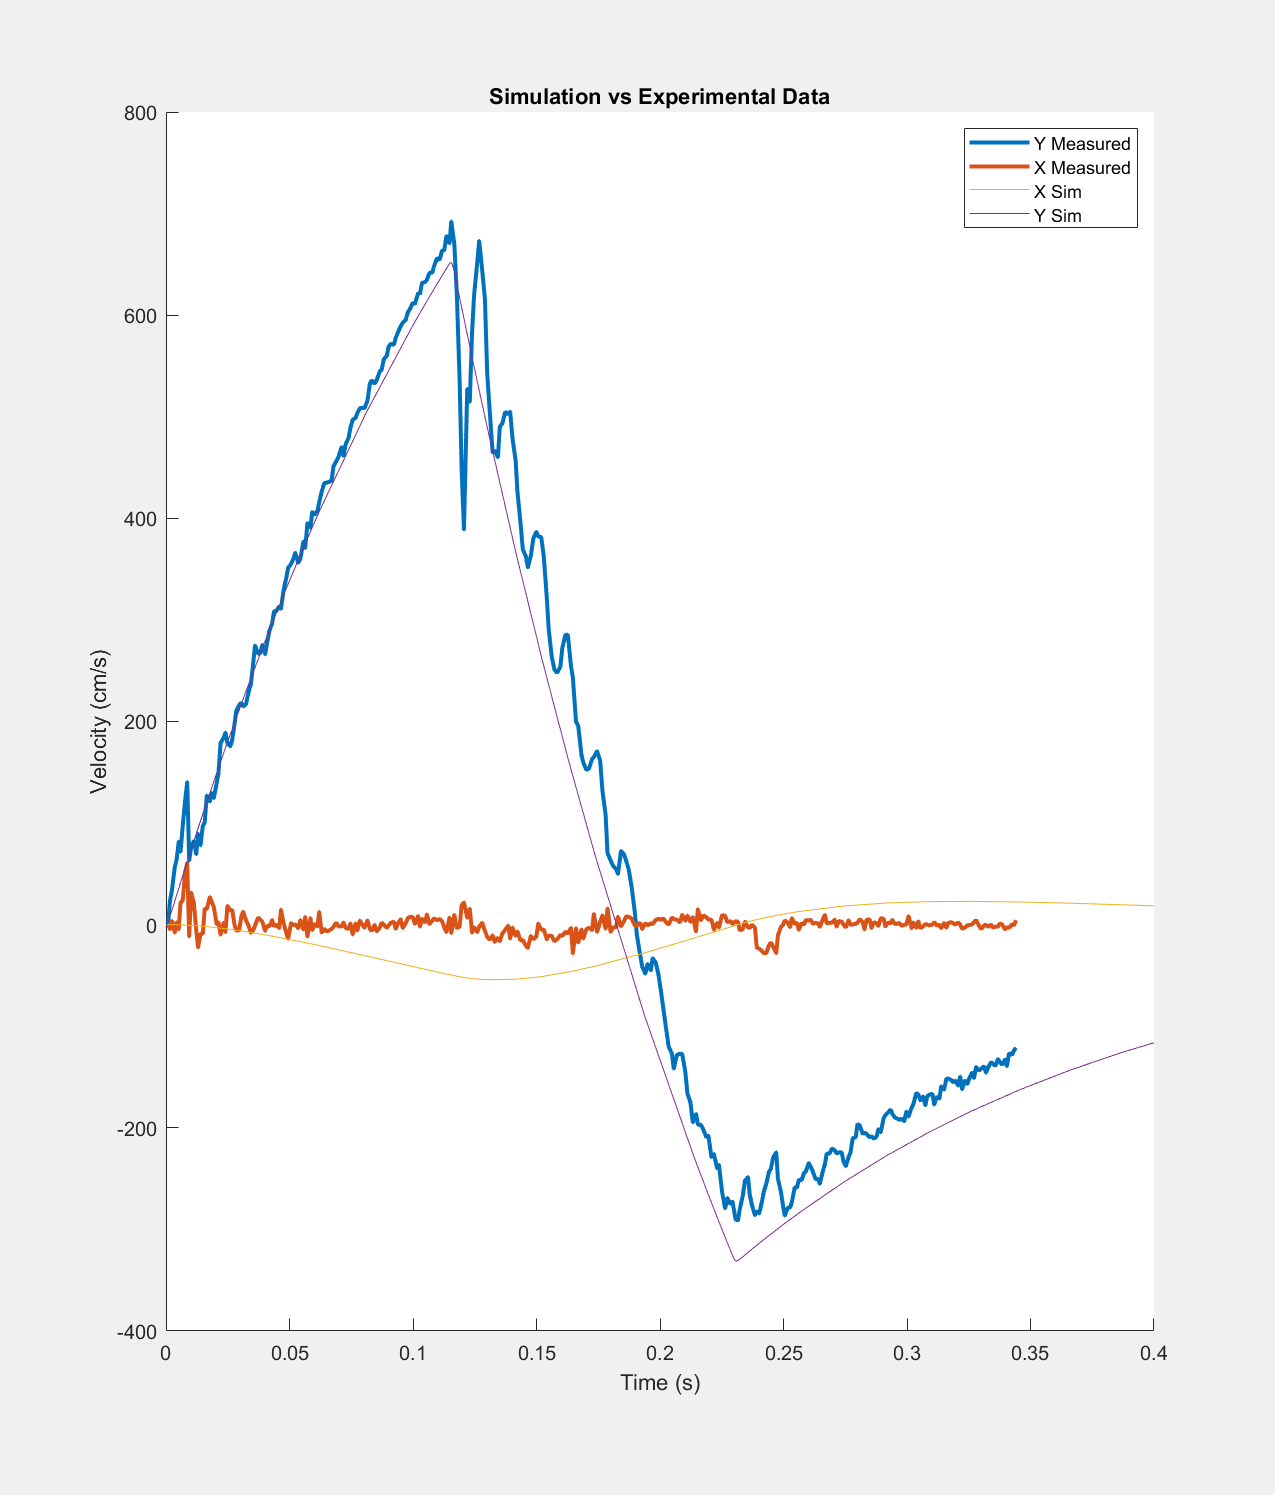

plot(out.simout.Time, out.simout.Data);
% xlim([0 0.25])
title('Simulation vs Experimental Data');
legend({'Y Measured', 'X Measured', 'X Sim', 'Y Sim'});
xlabel("Time (s)");
ylabel("Velocity (cm/s)");
xlim([0,0.4])



% % set(gcf, "visible", "on", 'position', [100 100 600 400])
% 
% resampledSim = resample(timeseries(out.simout), data.Time_ms_/1000);
% hold on
% plot(resampledSim.Time, movmean((-data.Left_Velocity_deg_s_ - resampledSim.Data)./resampledSim.Data, 10)*100)
% plot(resampledSim.Time, movmean((data.Right_Velocity_deg_s_ - resampledSim.Data)./resampledSim.Data, 10)*100)
% legend({'Left Motor', 'Right Motor'})
% xlim([0 6])
% ylim([-10 10])
% title('Angular Velocity Simulation Error')
% xlabel('Time (s)')
% ylabel('Percent Error (%)')